# 状態空間モデルによる失業率の再帰的予測

当サンプルは Econometrics Toolbox によって提供される状態空間モデルを Simulink モデルへ実装する方法を示します。ここでは以下のような線型な状態空間モデルを用いて米国における翌年の失業率を再帰的に推定しす


$$\begin{array}{l}
\left\lbrack \begin{array}{c}
x_t \\
x_{t-1} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\alpha_1  & \alpha_2 \\
1 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_{t-1} \\
x_{t-2} 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\varepsilon_t^{\left(1\right)} \\
\varepsilon_t^{\left(2\right)} 
\end{array}\right\rbrack \\
y_t -\beta \cdot z_t =\left\lbrack \begin{array}{cc}
1 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_t \\
x_{t-1} 
\end{array}\right\rbrack +w_t 
\end{array}$$


ただし、

$x_t :=\Delta X_t =X_t -X_{t-1} \;,{\;X}_t \;$: 実際の失業率

$y_t :=\Delta Y_t =Y_t -Y_{t-1} \;,{\;Y}_t \;$: 観測された失業率

$z_t :=\Delta Z_t =\log \left(Z_t -Z_{t-1} \right),{\;Z}_t \;$: 名目 GNP


$$\begin{array}{l}
\varepsilon_t^{\left(1\right)} \sim N\left(0,\sigma_{\varepsilon^{\left(1\right)} }^2 \right)\\
\varepsilon_t^{\left(2\right)} \sim N\left(0,\sigma_{\varepsilon^{\left(2\right)} }^2 \right)\\
w_t \sim N\left(0,\sigma_w^2 \right)
\end{array}$$


尚、当サンプルは Econometrics Toolbox によって提供されるこちらの例題に基づいております

[https://www.mathworks.com/help/econ/choose-state-space-model-specification-using-backtesting.html](https://www.mathworks.com/help/econ/choose-state-space-model-specification-using-backtesting.html)

[https://jp.mathworks.com/help/econ/rolling-window-estimation-of-state-space-models.html](https://jp.mathworks.com/help/econ/rolling-window-estimation-of-state-space-models.html)

## 1: 年次経済データをインポート

load Data_NelsonPlosser

※) 当経済データは米国のものです

## 2: インポートしたデータを前処理 

isNaN = any(ismissing(DataTable),2); % Flag periods containing NaNs
Z = DataTable.GNPN(~isNaN); % Nominal GNP
y = DataTable.UR(~isNaN); % Unemployment rate

## 3: 前処理したデータから時間付き部分時系列配列を作成

Simulink の "From Workspace" ブロック用に時間付き部分時系列配列を作成します

WindowSize = 31;
ForecastPeriod  = numel(y) - WindowSize + 1;

ZZ = zeros(ForecastPeriod, WindowSize);
yy = zeros(ForecastPeriod, WindowSize);

m = 1;
for nYear = 1:ForecastPeriod
    ZZ(nYear,:) = transpose(Z(m:m+WindowSize-1));
    yy(nYear,:) = transpose(y(m:m+WindowSize-1));
    m = m + 1;
end

Time = str2double(DataTable.Properties.RowNames(~isNaN));
Time = Time((end-ForecastPeriod+1:end));

% create arrays of sub time-series with time
ObsUnemployRate = [Time, yy];
nGNP = [Time, ZZ];

## 4: 状態空間モデルによるパラメータ推定および翌年の失業率の推定を再帰的に実施 (MATLAB編)

Simulink によるシミュレーションの実行前に、モデルの係数 $\left(\alpha_1 ,\alpha_2 ,\beta \right)$ に対するフィッティングと翌年の失業率の推定を MATLAB 上にて再帰的に実施します

eUR = zeros(numel(Time),1);
param0 = [0.5; 0.1; -20]; % initialize paramters

for t = 0:numel(Time)-1
    dlZ = diff(log(ZZ(t+1,:)))';
    dy  = diff(yy(t+1,:))';
    Mdl = ssm(@(c)rwAR2ParamMap(c,dy,dlZ));
    [Mdl, param0] = estimate(Mdl, dy, param0, 'Display', 'off');
    dyhat = forecast(Mdl, 1, dy,'Predictors0',dlZ,'PredictorsF',dlZ(end),'Beta',param0(end));
    eUR(t+1) = dyhat + yy(t+1,end);
end

## 5: 実際の失業率と MATLAB にて推定された失業率をプロット

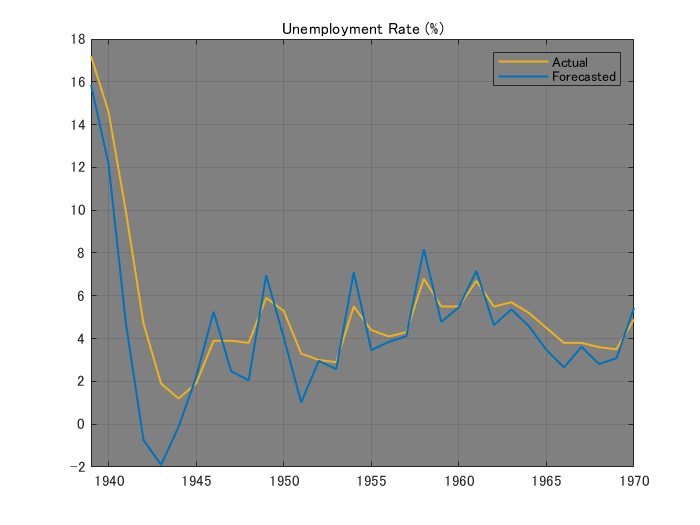

figure; axH = axes;
plot(axH, Time, y(end-numel(Time)+1:end), 'Color', [0.9290 0.6940 0.1250], 'LineWidth', 1.2);
hold(axH, 'on'); grid(axH, 'on');
plot(axH, Time, eUR, 'Color', [0 0.4470 0.7410], 'LineWidth', 1.2);
axH.XLim(1) = Time(1);
axH.Color = [0.5020 0.5020 0.5020];
axH.Title.String = 'Unemployment Rate (%)';
legend(["Actual", "Forecasted"])

## 6: Simulink モデルの開示とパラメータ設定

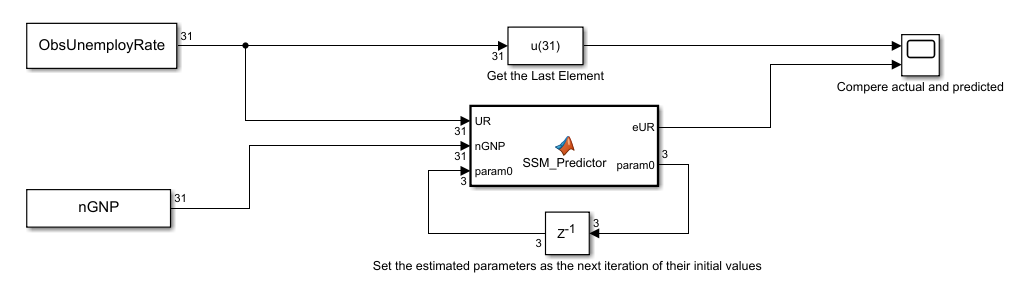

mdl = 'recursive_ssm_update';
open_system(mdl);

set_param(mdl, 'Solver', 'FixedStepAuto');
set_param(mdl, 'FixedStep', '1');
set_param(mdl, 'StartTime', num2str(Time(1)));
set_param(mdl, 'StopTime',  num2str(Time(end)));

## 7: 状態空間モデルによるパラメータ推定および翌年の失業率の推定を再帰的に実施 (Simulink編)

out = sim(mdl);

## 8: 実際の失業率と Simulink にて推定された失業率をプロット

figure; axH = axes;
plot(axH, Time, out.ScopeOut.signals(1).values, 'Color', [0.9290 0.6940 0.1250], 'LineWidth', 1.2);
hold(axH, 'on'); grid(axH, 'on');
plot(axH, Time, out.ScopeOut.signals(2).values, 'Color', [0 0.4470 0.7410], 'LineWidth', 1.2);
axH.XLim(1) = Time(1);
axH.Color = [0.5020 0.5020 0.5020];
axH.Title.String = 'Unemployment Rate (%)';
legend(["Actual", "Forecasted"])

## 9: MATLAB と Simulink の一致性検証 

isequal(out.ScopeOut.signals(2).values, eUR)

ans = logical
   1
